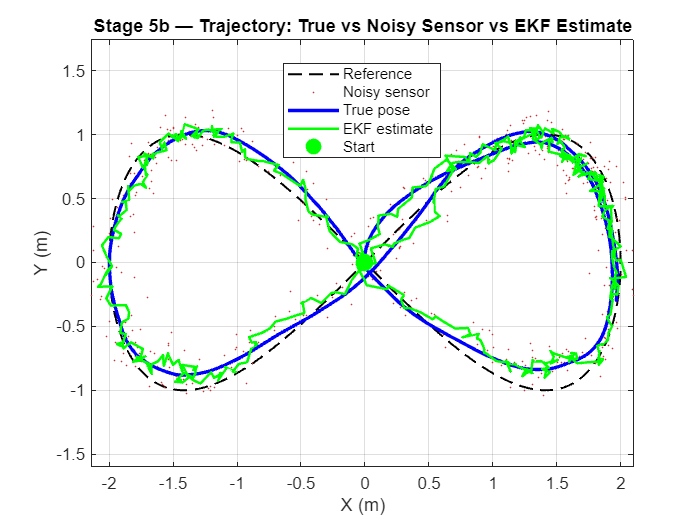

%% Stage 1: Differential Drive Robot — Kinematics
clc; clear; close all;

L  = 0.3;
dt = 0.05;
T  = 10;
N  = T / dt;

pose = [0; 0; 0];

vL = 0.8;
vR = 1.0;

history = zeros(3, N);

for k = 1:N
    history(:, k) = pose;

    v     = (vR + vL) / 2;
    omega = (vR - vL) / L;

    pose(1) = pose(1) + dt * v * cos(pose(3));
    pose(2) = pose(2) + dt * v * sin(pose(3));
    pose(3) = pose(3) + dt * omega;
end

figure;
plot(history(1,:), history(2,:), 'b-', LineWidth=2);
hold on;
plot(history(1,1), history(2,1), 'go', MarkerSize=10, MarkerFaceColor='g');
plot(history(1,end), history(2,end), 'rs', MarkerSize=10, MarkerFaceColor='r');
axis equal; grid on;
xlabel('X (m)'); ylabel('Y (m)');
title('Stage 1 — Open-Loop Differential Drive (Circular Arc)');
legend('Trajectory', 'Start', 'End', Location='best');

%% Stage 2: Reference Path + Pure Pursuit Steering
clc; clear; close all;

L       = 0.3;
dt      = 0.05;
T       = 20;
N       = T / dt;
v_base  = 0.8;
Ld      = 0.6;

t_path  = linspace(0, 2*pi, 500);
path_x  = 2.0 * sin(t_path);
path_y  = 1.0 * sin(2 * t_path);
path    = [path_x; path_y];

pose    = [0; 0; pi/2];

hist_pose   = zeros(3, N);
hist_error  = zeros(1, N);

for k = 1:N
    hist_pose(:, k) = pose;
    x = pose(1); y = pose(2); theta = pose(3);

    dists   = sqrt((path(1,:) - x).^2 + (path(2,:) - y).^2);
    [~, idx] = min(dists);

    look_idx = idx;
    for j = idx:size(path,2)
        if sqrt((path(1,j)-x)^2 + (path(2,j)-y)^2) >= Ld
            look_idx = j;
            break;
        end
    end

    dx          = path(1, look_idx) - x;
    dy          = path(2, look_idx) - y;
    theta_ref   = atan2(dy, dx);

    e_theta     = atan2(sin(theta_ref - theta), cos(theta_ref - theta));
    hist_error(k) = e_theta;

    Kp_steer    = 2.0;
    omega       = Kp_steer * e_theta;

    vR = v_base + (omega * L / 2);
    vL = v_base - (omega * L / 2);

    v       = (vR + vL) / 2;
    pose(1) = x + dt * v * cos(theta);
    pose(2) = y + dt * v * sin(theta);
    pose(3) = theta + dt * (vR - vL) / L;
end

figure;
plot(path_x, path_y, 'k--', LineWidth=1.5); hold on;
plot(hist_pose(1,:), hist_pose(2,:), 'b-', LineWidth=2);
plot(hist_pose(1,1), hist_pose(2,1), 'go', MarkerSize=10, MarkerFaceColor='g');
axis equal; grid on;
xlabel('X (m)'); ylabel('Y (m)');
title('Stage 2 — Pure Pursuit Path Following (Figure-8)');
legend('Reference Path', 'Robot Trajectory', 'Start', Location='best');

figure;
t_vec = (0:N-1) * dt;
plot(t_vec, rad2deg(hist_error), 'r-', LineWidth=1.5);
yline(0, 'k--');
xlabel('Time (s)'); ylabel('Heading Error (deg)');
title('Stage 2 — Heading Error (this is what PID will correct)');
grid on;

%% Stage 3: PID Controller — Fixed Path Indexing + Retuned Gains
clc; clear; close all;

L       = 0.3;
dt      = 0.05;
T       = 25;
N       = T / dt;
v_base  = 0.8;
Ld      = 0.5;

Kp    = 3.0;
Ki    = 0.3;
Kd    = 0.08;
i_max = 1.0;

n_path = 800;
t_path = linspace(0, 2*pi, n_path);
path_x = 2.0 * sin(t_path);
path_y = 1.0 * sin(2 * t_path);
path   = [path_x; path_y];

pose    = [0; 0; pi/2];
e_prev   = 0;
e_int    = 0;
path_idx = 1;

hist_pose  = zeros(3, N);
hist_error = zeros(1, N);
hist_terms = zeros(3, N);

for k = 1:N
    hist_pose(:, k) = pose;
    x = pose(1); y = pose(2); theta = pose(3);

    search_window = 60;
    best_dist = inf;
    best_idx  = path_idx;
    for j = 0:search_window
        idx_j = mod(path_idx + j - 1, n_path) + 1;
        d = sqrt((path(1,idx_j)-x)^2 + (path(2,idx_j)-y)^2);
        if d < best_dist
            best_dist = d;
            best_idx  = idx_j;
        end
    end
    path_idx = best_idx;

    look_idx = path_idx;
    for j = 0:n_path-1
        idx_j = mod(path_idx + j - 1, n_path) + 1;
        if sqrt((path(1,idx_j)-x)^2 + (path(2,idx_j)-y)^2) >= Ld
            look_idx = idx_j;
            break;
        end
    end

    dx        = path(1, look_idx) - x;
    dy        = path(2, look_idx) - y;
    theta_ref = atan2(dy, dx);
    e_theta   = atan2(sin(theta_ref - theta), cos(theta_ref - theta));

    e_int   = e_int + e_theta * dt;
    e_int   = max(-i_max, min(i_max, e_int));
    e_dot   = (e_theta - e_prev) / dt;

    term_P  = Kp * e_theta;
    term_I  = Ki * e_int;
    term_D  = Kd * e_dot;
    omega   = term_P + term_I + term_D;

    hist_error(k)   = e_theta;
    hist_terms(:,k) = [term_P; term_I; term_D];
    e_prev          = e_theta;

    vR = v_base + (omega * L / 2);
    vL = v_base - (omega * L / 2);

    v       = (vR + vL) / 2;
    pose(1) = x + dt * v * cos(theta);
    pose(2) = y + dt * v * sin(theta);
    pose(3) = theta + dt * (vR - vL) / L;
end

t_vec = (0:N-1) * dt;

figure;
plot(path_x, path_y, 'k--', LineWidth=1.5); hold on;
plot(hist_pose(1,:), hist_pose(2,:), 'b-', LineWidth=2);
plot(hist_pose(1,1), hist_pose(2,1), 'go', MarkerSize=10, MarkerFaceColor='g');
axis equal; grid on;
xlabel('X (m)'); ylabel('Y (m)');
title('Stage 3 (Fixed) — PID Controlled Path Following');
legend('Reference Path', 'Robot Trajectory', 'Start', Location='best');

figure;
plot(t_vec, rad2deg(hist_error), 'b-', LineWidth=1.5);
yline(0, 'k--'); yline(5,'g:',LineWidth=1); yline(-5,'g:',LineWidth=1);
xlabel('Time (s)'); ylabel('Heading Error (deg)');
title('Stage 3 (Fixed) — Heading Error with PID');
legend('PID Error','Zero','±5° band', Location='best');
grid on;

figure;
plot(t_vec, hist_terms(1,:), 'r-', LineWidth=1.5); hold on;
plot(t_vec, hist_terms(2,:), 'g-', LineWidth=1.5);
plot(t_vec, hist_terms(3,:), 'b-', LineWidth=1.5);
xlabel('Time (s)'); ylabel('Control Contribution (rad/s)');
title('Stage 3 (Fixed) — PID Term Breakdown');
legend('Proportional','Integral','Derivative', Location='best');
ylim([-3 3]); grid on;

%% Stage 4: Disturbance Injection & PID Recovery
clc; clear; close all;

L       = 0.3;
dt      = 0.05;
T       = 25;
N       = T / dt;
v_base  = 0.8;
Ld      = 0.5;
n_path  = 800;

Kp    = 3.0;
Ki    = 0.3;
Kd    = 0.08;
i_max = 1.0;

t_path = linspace(0, 2*pi, n_path);
path_x = 2.0 * sin(t_path);
path_y = 1.0 * sin(2 * t_path);
path   = [path_x; path_y];

disturbances = [
    5.0,  5.8,  0.2,  1.0;
   14.0, 14.8,  1.0,  0.2;
];

pose     = [0; 0; pi/2];
e_prev   = 0; e_int = 0;
path_idx = 1;
hist_pid      = zeros(3, N);
hist_err_pid  = zeros(1, N);
hist_disturb  = zeros(1, N);

for k = 1:N
    hist_pid(:, k) = pose;
    x = pose(1); y = pose(2); theta = pose(3);
    t = (k-1) * dt;

    best_dist = inf; best_idx = path_idx;
    for j = 0:60
        idx_j = mod(path_idx + j - 1, n_path) + 1;
        d = sqrt((path(1,idx_j)-x)^2 + (path(2,idx_j)-y)^2);
        if d < best_dist; best_dist = d; best_idx = idx_j; end
    end
    path_idx = best_idx;

    look_idx = path_idx;
    for j = 0:n_path-1
        idx_j = mod(path_idx + j - 1, n_path) + 1;
        if sqrt((path(1,idx_j)-x)^2 + (path(2,idx_j)-y)^2) >= Ld
            look_idx = idx_j; break;
        end
    end

    e_theta = atan2(sin(atan2(path(2,look_idx)-y, path(1,look_idx)-x) - theta), ...
                    cos(atan2(path(2,look_idx)-y, path(1,look_idx)-x) - theta));

    e_int = max(-i_max, min(i_max, e_int + e_theta * dt));
    omega = Kp*e_theta + Ki*e_int + Kd*(e_theta - e_prev)/dt;
    e_prev = e_theta;
    hist_err_pid(k) = e_theta;

    vR = v_base + (omega * L / 2);
    vL = v_base - (omega * L / 2);

    d_scale_L = 1.0; d_scale_R = 1.0;
    for d = 1:size(disturbances,1)
        if t >= disturbances(d,1) && t <= disturbances(d,2)
            d_scale_L = disturbances(d,3);
            d_scale_R = disturbances(d,4);
            hist_disturb(k) = 1;
        end
    end
    vL = vL * d_scale_L;
    vR = vR * d_scale_R;

    v = (vR+vL)/2;
    pose(1) = x + dt*v*cos(theta);
    pose(2) = y + dt*v*sin(theta);
    pose(3) = theta + dt*(vR-vL)/L;
end

pose     = [0; 0; pi/2];
path_idx = 1;
hist_nopid     = zeros(3, N);
hist_err_nopid = zeros(1, N);

for k = 1:N
    hist_nopid(:, k) = pose;
    x = pose(1); y = pose(2); theta = pose(3);
    t = (k-1) * dt;

    best_dist = inf; best_idx = path_idx;
    for j = 0:60
        idx_j = mod(path_idx + j - 1, n_path) + 1;
        d = sqrt((path(1,idx_j)-x)^2 + (path(2,idx_j)-y)^2);
        if d < best_dist; best_dist = d; best_idx = idx_j; end
    end
    path_idx = best_idx;

    look_idx = path_idx;
    for j = 0:n_path-1
        idx_j = mod(path_idx + j - 1, n_path) + 1;
        if sqrt((path(1,idx_j)-x)^2 + (path(2,idx_j)-y)^2) >= Ld
            look_idx = idx_j; break;
        end
    end

    e_theta = atan2(sin(atan2(path(2,look_idx)-y, path(1,look_idx)-x) - theta), ...
                    cos(atan2(path(2,look_idx)-y, path(1,look_idx)-x) - theta));
    hist_err_nopid(k) = e_theta;

    omega = 2.0 * e_theta;
    vR = v_base + (omega * L / 2);
    vL = v_base - (omega * L / 2);

    d_scale_L = 1.0; d_scale_R = 1.0;
    for d = 1:size(disturbances,1)
        if t >= disturbances(d,1) && t <= disturbances(d,2)
            d_scale_L = disturbances(d,3);
            d_scale_R = disturbances(d,4);
        end
    end
    vL = vL * d_scale_L;
    vR = vR * d_scale_R;

    v = (vR+vL)/2;
    pose(1) = x + dt*v*cos(theta);
    pose(2) = y + dt*v*sin(theta);
    pose(3) = theta + dt*(vR-vL)/L;
end

t_vec = (0:N-1)*dt;

figure;
plot(path_x, path_y, 'k--', LineWidth=1.5); hold on;
plot(hist_nopid(1,:), hist_nopid(2,:), 'r-',  LineWidth=1.8);
plot(hist_pid(1,:),   hist_pid(2,:),   'b-',  LineWidth=2);
for d = 1:size(disturbances,1)
    k1 = max(1, round(disturbances(d,1)/dt));
    k2 = min(N, round(disturbances(d,2)/dt));
    plot(hist_pid(1,k1:k2), hist_pid(2,k1:k2), 'm-', LineWidth=4);
end
plot(hist_pid(1,1), hist_pid(2,1), 'go', MarkerSize=10, MarkerFaceColor='g');
axis equal; grid on;
xlabel('X (m)'); ylabel('Y (m)');
title('Stage 4 — Disturbance: PID vs No-PID');
legend('Reference','No PID (P-only)','With PID','Disturbance active','Start', ...
       Location='best');

figure;
for d = 1:size(disturbances,1)
    patch([disturbances(d,1) disturbances(d,2) disturbances(d,2) disturbances(d,1)], ...
          [-200 -200 200 200], [1 0.8 0.8], EdgeColor='none', FaceAlpha=0.4);
    hold on;
end
plot(t_vec, rad2deg(hist_err_nopid), 'r-', LineWidth=1.5);
plot(t_vec, rad2deg(hist_err_pid),   'b-', LineWidth=1.5);
yline(0,'k--'); yline(5,'g:',LineWidth=1); yline(-5,'g:',LineWidth=1);
ylim([-60 60]);
xlabel('Time (s)'); ylabel('Heading Error (deg)');
title('Stage 4 — Heading Error: PID vs No-PID (pink = disturbance active)');
legend('Disturbance window','No PID','With PID','Zero','±5° band', Location='best');
grid on;

figure;
cte_pid   = zeros(1,N);
cte_nopid = zeros(1,N);
for k = 1:N
    dists = sqrt((path(1,:)-hist_pid(1,k)).^2   + (path(2,:)-hist_pid(2,k)).^2);
    cte_pid(k) = min(dists);
    dists = sqrt((path(1,:)-hist_nopid(1,k)).^2 + (path(2,:)-hist_nopid(2,k)).^2);
    cte_nopid(k) = min(dists);
end
for d = 1:size(disturbances,1)
    patch([disturbances(d,1) disturbances(d,2) disturbances(d,2) disturbances(d,1)], ...
          [0 0 2 2], [1 0.8 0.8], EdgeColor='none', FaceAlpha=0.4); hold on;
end
plot(t_vec, cte_nopid, 'r-', LineWidth=1.5); hold on;
plot(t_vec, cte_pid,   'b-', LineWidth=1.5);
xlabel('Time (s)'); ylabel('Cross-track Error (m)');
title('Stage 4 — Cross-Track Error: PID vs No-PID');
legend('Disturbance window','No PID','With PID', Location='best');
grid on;

%% Stage 5a: Speed-Adaptive PID (curvature-based speed control)
clc; clear; close all;

L      = 0.3;
dt     = 0.05;
T      = 25;
N      = T / dt;
n_path = 800;

v_max     = 1.2;
v_min     = 0.3;
kappa_max = 1.2;

Kp = 3.0;  Ki = 0.3;  Kd = 0.08;  i_max = 1.0;

t_path = linspace(0, 2*pi, n_path);
path_x = 2.0 * sin(t_path);
path_y = 1.0 * sin(2 * t_path);
path   = [path_x; path_y];

dx  = gradient(path_x);
dy  = gradient(path_y);
ddx = gradient(dx);
ddy = gradient(dy);
kappa = abs(dx .* ddy - dy .* ddx) ./ (dx.^2 + dy.^2).^1.5;
kappa = min(kappa, kappa_max);

pose     = [0; 0; pi/2];
e_prev   = 0;  e_int = 0;
path_idx = 1;

hist_pose  = zeros(3, N);
hist_error = zeros(1, N);
hist_speed = zeros(1, N);
hist_kappa = zeros(1, N);

for k = 1:N
    hist_pose(:, k) = pose;
    x = pose(1);  y = pose(2);  theta = pose(3);

    best_dist = inf;  best_idx = path_idx;
    for j = 0:60
        idx_j = mod(path_idx + j - 1, n_path) + 1;
        d = sqrt((path(1,idx_j)-x)^2 + (path(2,idx_j)-y)^2);
        if d < best_dist;  best_dist = d;  best_idx = idx_j;  end
    end
    path_idx = best_idx;

    look_idx = path_idx;
    for j = 0:n_path-1
        idx_j = mod(path_idx + j - 1, n_path) + 1;
        if sqrt((path(1,idx_j)-x)^2 + (path(2,idx_j)-y)^2) >= 0.5
            look_idx = idx_j;  break;
        end
    end

    k_cur  = kappa(path_idx);
    v_base = v_max - (v_max - v_min) * (k_cur / kappa_max);
    v_base = max(v_min, min(v_max, v_base));

    hist_speed(k) = v_base;
    hist_kappa(k) = k_cur;

    dx_     = path(1, look_idx) - x;
    dy_     = path(2, look_idx) - y;
    e_theta = atan2(sin(atan2(dy_, dx_) - theta), cos(atan2(dy_, dx_) - theta));

    e_int   = max(-i_max, min(i_max, e_int + e_theta * dt));
    e_dot   = (e_theta - e_prev) / dt;
    omega   = Kp*e_theta + Ki*e_int + Kd*e_dot;
    e_prev  = e_theta;
    hist_error(k) = e_theta;

    vR = v_base + (omega * L / 2);
    vL = v_base - (omega * L / 2);

    v       = (vR + vL) / 2;
    pose(1) = x + dt * v * cos(theta);
    pose(2) = y + dt * v * sin(theta);
    pose(3) = theta + dt * (vR - vL) / L;
end

t_vec = (0:N-1) * dt;

figure;
plot(path_x, path_y, 'k--', LineWidth=1.5); hold on;
plot(hist_pose(1,:), hist_pose(2,:), 'b-', LineWidth=2);
plot(hist_pose(1,1), hist_pose(2,1), 'go', MarkerSize=10, MarkerFaceColor='g');
axis equal; grid on;
xlabel('X (m)'); ylabel('Y (m)');
title('Stage 5a — Speed-Adaptive PID Trajectory');
legend('Reference','Robot','Start', Location='best');

figure;
plot(t_vec, hist_speed, 'r-', LineWidth=1.8); hold on;
yline(v_max, 'k--', 'v_{max}', LineWidth=1, LabelHorizontalAlignment='left');
yline(v_min, 'k:', 'v_{min}',  LineWidth=1, LabelHorizontalAlignment='left');
xlabel('Time (s)'); ylabel('v_{base} (m/s)');
title('Stage 5a — Commanded Speed (dips at curves, peaks on straights)');
ylim([0 1.4]); grid on;

figure;
yyaxis left
plot(t_vec, hist_speed, 'r-', LineWidth=1.5);
ylabel('Speed (m/s)'); ylim([0 1.4]);
yyaxis right
plot(t_vec, rad2deg(hist_error), 'b-', LineWidth=1.2);
ylabel('Heading Error (deg)'); ylim([-40 40]);
yline(0, 'k--');
xlabel('Time (s)');
title('Stage 5a — Speed vs Heading Error (speed drops tame the error)');
legend('Speed','Heading error', Location='best');
grid on;

%% Stage 5b: EKF — Odometry-Driven Kalman Filter + Sensor Noise
clc; clear; close all;
rng(42);

% ── Parameters ────────────────────────────────────────────────────
L      = 0.3;
dt     = 0.05;
T      = 25;
N      = T / dt;
n_path = 800;

v_max     = 1.2;   v_min = 0.3;   kappa_max = 1.2;
Kp = 3.0;  Ki = 0.3;  Kd = 0.08;  i_max = 1.0;

% ── Reference Path ────────────────────────────────────────────────
t_path = linspace(0, 2*pi, n_path);
path_x = 2.0 * sin(t_path);
path_y = 1.0 * sin(2 * t_path);
path   = [path_x; path_y];

dx  = gradient(path_x);   dy  = gradient(path_y);
ddx = gradient(dx);       ddy = gradient(dy);
kappa = abs(dx.*ddy - dy.*ddx) ./ (dx.^2 + dy.^2).^1.5;
kappa = min(kappa, kappa_max);

% ── Sensor Noise ──────────────────────────────────────────────────
sigma_xy    = 0.09;
sigma_theta = 0.055;

% ── EKF Setup ─────────────────────────────────────────────────────
% H: observation matrix — we directly measure [x; y; theta]
H = eye(3);

% Q: process noise — small, we trust the kinematic model
Q = diag([0.002, 0.002, 0.0008]);

% R: measurement noise — must match sigma values
R = diag([sigma_xy^2, sigma_xy^2, sigma_theta^2]);

% Initial EKF state and covariance
x_est = [0; 0; pi/2];
P     = eye(3) * 0.1;

% ── Initial True Pose ─────────────────────────────────────────────
pose     = [0; 0; pi/2];
e_prev   = 0;  e_int = 0;
path_idx = 1;

% ── Storage ───────────────────────────────────────────────────────
hist_true   = zeros(3, N);
hist_noisy  = zeros(3, N);
hist_kalman = zeros(3, N);
hist_error  = zeros(1, N);
hist_speed  = zeros(1, N);
hist_K_diag = zeros(3, N);

% ── EKF + Control Loop ────────────────────────────────────────────
for k = 1:N
    hist_true(:, k) = pose;

    % 1. Noisy sensor measurement of true pose
    noise = [sigma_xy * randn; sigma_xy * randn; sigma_theta * randn];
    z     = pose + noise;
    hist_noisy(:, k) = z;

    % 2. Path following using current EKF estimate
    x = x_est(1);  y = x_est(2);  theta = x_est(3);

    best_dist = inf;  best_idx = path_idx;
    for j = 0:60
        idx_j = mod(path_idx + j - 1, n_path) + 1;
        d = sqrt((path(1,idx_j)-x)^2 + (path(2,idx_j)-y)^2);
        if d < best_dist;  best_dist = d;  best_idx = idx_j;  end
    end
    path_idx = best_idx;

    look_idx = path_idx;
    for j = 0:n_path-1
        idx_j = mod(path_idx + j - 1, n_path) + 1;
        if sqrt((path(1,idx_j)-x)^2 + (path(2,idx_j)-y)^2) >= 0.5
            look_idx = idx_j;  break;
        end
    end

    k_cur  = kappa(path_idx);
    v_base = v_max - (v_max - v_min) * (k_cur / kappa_max);
    v_base = max(v_min, min(v_max, v_base));
    hist_speed(k) = v_base;

    dx_     = path(1, look_idx) - x;
    dy_     = path(2, look_idx) - y;
    e_theta = atan2(sin(atan2(dy_, dx_) - theta), cos(atan2(dy_, dx_) - theta));

    e_int  = max(-i_max, min(i_max, e_int + e_theta * dt));
    e_dot  = (e_theta - e_prev) / dt;
    omega  = Kp*e_theta + Ki*e_int + Kd*e_dot;
    e_prev = e_theta;
    hist_error(k) = e_theta;

    vR = v_base + (omega * L / 2);
    vL = v_base - (omega * L / 2);

    % 3. EKF Predict — use odometry commands as motion model
    v_cmd = (vR + vL) / 2;
    w_cmd = (vR - vL) / L;
    th    = x_est(3);

    x_pred = x_est + [dt * v_cmd * cos(th);
                       dt * v_cmd * sin(th);
                       dt * w_cmd];

    % Jacobian of motion model (linearisation for EKF)
    F = [1, 0, -dt * v_cmd * sin(th);
         0, 1,  dt * v_cmd * cos(th);
         0, 0,  1];

    P_pred = F * P * F' + Q;

    % 4. EKF Update — fuse prediction with noisy measurement
    S      = H * P_pred * H' + R;
    K      = P_pred * H' / S;
    innov  = z - H * x_pred;
    innov(3) = atan2(sin(innov(3)), cos(innov(3)));   % wrap angle

    x_est  = x_pred + K * innov;
    P      = (eye(3) - K * H) * P_pred;

    hist_kalman(:, k) = x_est;
    hist_K_diag(:, k) = diag(K);

    % 5. Euler integration on TRUE pose
    v = (vR + vL) / 2;
    pose(1) = pose(1) + dt * v * cos(pose(3));
    pose(2) = pose(2) + dt * v * sin(pose(3));
    pose(3) = pose(3) + dt * (vR - vL) / L;
end

t_vec = (0:N-1) * dt;

% ── Plot 1: Trajectory ────────────────────────────────────────────
figure;
plot(path_x, path_y, 'k--', LineWidth=1.2); hold on;
plot(hist_noisy(1,:),  hist_noisy(2,:),  '.', Color=[0.8 0.2 0.2], MarkerSize=3);
plot(hist_true(1,:),   hist_true(2,:),   'b-', LineWidth=2);
plot(hist_kalman(1,:), hist_kalman(2,:), 'g-', LineWidth=1.5);
plot(hist_true(1,1),   hist_true(2,1),   'go', MarkerSize=10, MarkerFaceColor='g');
axis equal; grid on;
xlabel('X (m)'); ylabel('Y (m)');
title('Stage 5b — Trajectory: True vs Noisy Sensor vs EKF Estimate');
legend('Reference','Noisy sensor','True pose','EKF estimate','Start', Location='best');

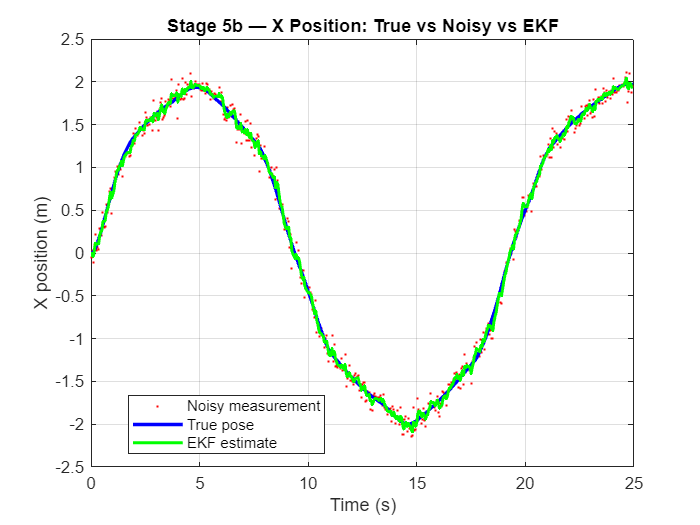


% ── Plot 2: X position ────────────────────────────────────────────
figure;
plot(t_vec, hist_noisy(1,:),  'r.', MarkerSize=4); hold on;
plot(t_vec, hist_true(1,:),   'b-', LineWidth=2);
plot(t_vec, hist_kalman(1,:), 'g-', LineWidth=1.8);
xlabel('Time (s)'); ylabel('X position (m)');
title('Stage 5b — X Position: True vs Noisy vs EKF');
legend('Noisy measurement','True pose','EKF estimate', Location='best');
grid on;

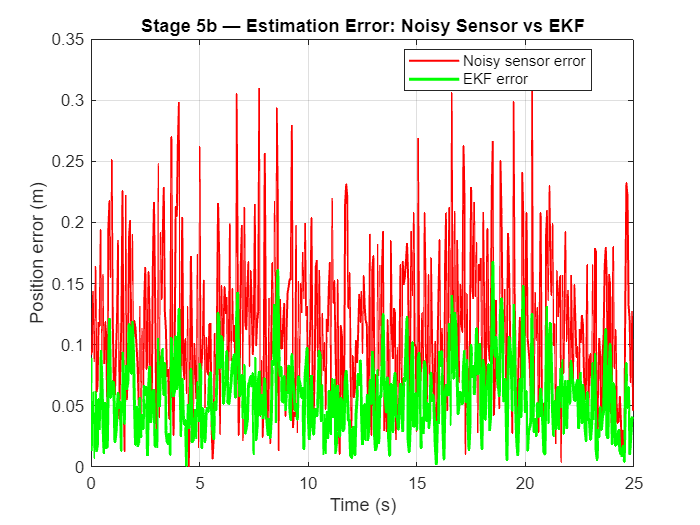


% ── Plot 3: Estimation error ──────────────────────────────────────
err_noisy  = sqrt((hist_noisy(1,:)  - hist_true(1,:)).^2 + ...
                  (hist_noisy(2,:)  - hist_true(2,:)).^2);
err_kalman = sqrt((hist_kalman(1,:) - hist_true(1,:)).^2 + ...
                  (hist_kalman(2,:) - hist_true(2,:)).^2);

figure;
plot(t_vec, err_noisy,  'r-', LineWidth=1.2); hold on;
plot(t_vec, err_kalman, 'g-', LineWidth=1.8);
xlabel('Time (s)'); ylabel('Position error (m)');
title('Stage 5b — Estimation Error: Noisy Sensor vs EKF');
legend('Noisy sensor error','EKF error', Location='best');
grid on;

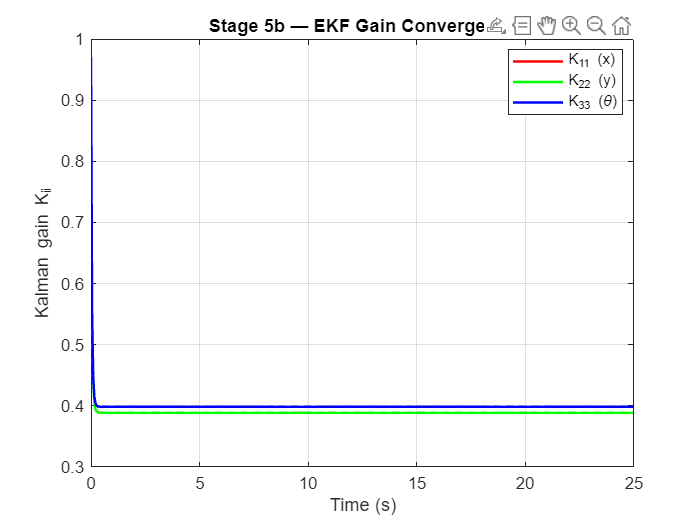


% ── Plot 4: Kalman gain convergence ──────────────────────────────
figure;
plot(t_vec, hist_K_diag(1,:), 'r-', LineWidth=1.5); hold on;
plot(t_vec, hist_K_diag(2,:), 'g-', LineWidth=1.5);
plot(t_vec, hist_K_diag(3,:), 'b-', LineWidth=1.5);
xlabel('Time (s)'); ylabel('Kalman gain K_{ii}');
title('Stage 5b — EKF Gain Convergence');
legend('K_{11} (x)', 'K_{22} (y)', 'K_{33} (\theta)', Location='best');
grid on;


% ── RMS Summary ───────────────────────────────────────────────────
rms_noisy  = sqrt(mean(err_noisy.^2));
rms_kalman = sqrt(mean(err_kalman.^2));
fprintf('\n── EKF Estimation Performance ──────────────\n');


── EKF Estimation Performance ──────────────


fprintf('RMS error  |  Noisy sensor : %.4f m\n', rms_noisy);

RMS error  |  Noisy sensor : 0.1322 m


fprintf('RMS error  |  EKF estimate  : %.4f m\n', rms_kalman);

RMS error  |  EKF estimate  : 0.0648 m


fprintf('Improvement : %.1f%%\n', (1 - rms_kalman/rms_noisy)*100);

Improvement : 51.0%


fprintf('────────────────────────────────────────────\n');

────────────────────────────────────────────
